clear;clc;
% --- paths (use your original logic) ---
if exist('I:\', 'dir')
    input_path = 'I:\My Drive\Data\New Data\EEG epoched\';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('G:\', 'dir')
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end

conditions = {'BLT','P1'}; %,'BLT','P1','P2','P3'
num_ch = 32;
expected_num_time = 1792;
fs = []; % will set from EEG.srate on first load

%% 1.1 Load and import file as EEGLAB matrix
data_BLT = [];
data_P1 = [];

% Loop through the conditions and load the files
for c = 1:length(conditions)
    condition = conditions{c};
    in_dir = fullfile(input_path, condition);
    set_files = dir(fullfile(in_dir, '*.set'));
    names_sorted = sort(cellstr({set_files.name})');
    
    if isempty(names_sorted)
        fprintf('No .set files for %s — skipping\n', condition);
        continue;
    end
    
    % We will load the 10th file in the sorted list, just like your draft
    file_to_load = names_sorted{10}; 
    fprintf('Loading %s for condition: %s\n', file_to_load, condition);
    
    EEG = pop_loadset('filename', file_to_load, 'filepath', in_dir);
    if isempty(fs), fs = EEG.srate; end
    
    % Choose odd/even indexing based on condition
    if ismember(condition, {'BLA','P1','P2','P3'})
        epoch_trials = 1:2:EEG.trials;
    else
        epoch_trials = 2:2:EEG.trials;
    end
    
    % Extract and store the data based on which condition is currently looping
    if strcmp(condition, 'BLT')
        data_BLT = EEG.data(:, :, epoch_trials);
    elseif strcmp(condition, 'P1')
        data_P1 = EEG.data(:, :, epoch_trials);
    end
end

Loading binepochs filtered ICArej BLTAvgBOS5.set for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading binepochs filtered ICArej P1AvgBOS5.set for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


nTime = size(data_BLT, 2);
time_ms_eeg = linspace(0, 3.5, nTime); % Rebuild the time vector

fprintf('Loaded BLT trials: %d | Loaded P1 trials: %d\n', size(data_BLT,3), size(data_P1,3));

Loaded BLT trials: 60 | Loaded P1 trials: 60


## 1.2 Visualizing the EEG for the first trial (BLT vs P1)

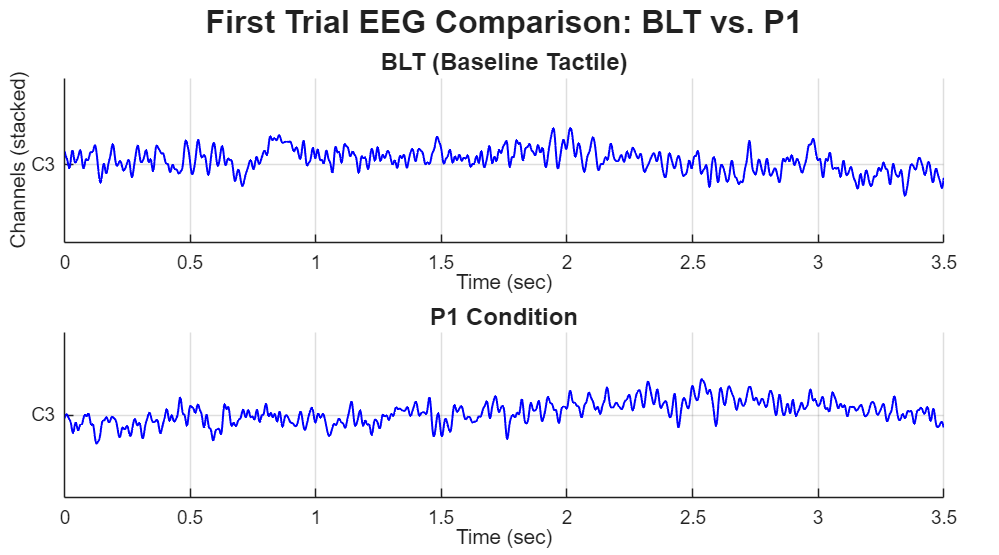

num_channels_plot = 1;
T_subject = 3.5; % duration of each trial
display_channels = 1:1:num_channels_plot;
display_channels_str = {EEG.chanlocs.labels};

% Made the figure slightly wider (1600) to comfortably fit two plots side-by-side
figure('Position',[50 50 1800 1000])
t = tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'First Trial EEG Comparison: BLT vs. P1', 'FontSize', 24, 'FontWeight', 'bold');

offset = 30; % vertical spacing between channels
tick_positions = (num_channels_plot - display_channels) * offset;

% =========================
% PLOT 1: BLT Condition
% =========================
nexttile;
hold on
for ch = 1:num_channels_plot
    plot(time_ms_eeg, squeeze(data_BLT(14, :, 1)) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.5);
end
hold off

xlim([0 3.5]);
ylim([-offset, num_channels_plot*offset]);
xlabel('Time (sec)');
ylabel('Channels (stacked)');
yticks(flip(tick_positions));
yticklabels(flip(string(display_channels_str(14))));
set(gca,'FontSize',14);
title('BLT (Baseline Tactile)', 'FontSize', 18);
grid on;

% =========================
% PLOT 2: P1 Condition
% =========================
nexttile;
hold on
for ch = 1:num_channels_plot
    plot(time_ms_eeg, squeeze(data_P1(14, :, 1)) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.5);
end
hold off

xlim([0 3.5]);
ylim([-offset, num_channels_plot*offset]);
xlabel('Time (sec)');
% Y-axis labels repeated for easy reading across the wide figure
yticks(flip(tick_positions));
yticklabels(flip(string(display_channels_str(14))));
set(gca,'FontSize',14);
title('P1 Condition', 'FontSize', 18);
grid on;

BLT_C3 = data_BLT(14, :, 1);
P1_C3 = data_P1(14, :, 1);

T = size(BLT_C3, 2);
trial_dur = 1; 
L = round(trial_dur * fs);
nTrials = floor(T/L);
f_axis = (0:L-1)*(fs/L);
nHz = floor(L/2) + 1;
f_plot = f_axis(1:nHz);

BLT_C3_Hz = zeros(L, nTrials);
P1_C3_Hz = zeros(L, nTrials);

% --- FFT Calculation ---
for tr = 1:nTrials
    idx = (tr-1)*L + (1:L);
    BLT_C3_Hz(:,tr) = fft(BLT_C3(idx));
    P1_C3_Hz(:,tr) = fft(P1_C3(idx));
end

BLT_C3_Hz_avg = mean(abs(BLT_C3_Hz(1:nHz, :)), 2);
P1_C3_Hz_avg = mean(abs(P1_C3_Hz(1:nHz, :)), 2);

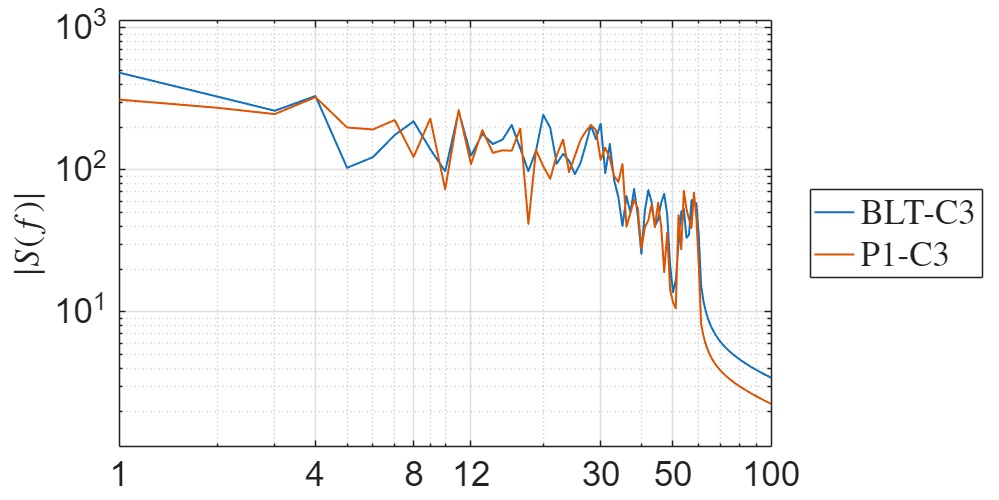

fig = figure('Position', [100, 100, 1000, 500]);
tiledlayout(1, 1, 'TileSpacing', 'compact' , 'Padding', 'compact'); 

% Plot 1: True Spectrum
ax1 = nexttile; 

loglog(f_plot, BLT_C3_Hz_avg, 'LineWidth', 1.5, 'DisplayName', 'BLT-C3');
hold on;
loglog(f_plot, P1_C3_Hz_avg, 'LineWidth', 1.5, 'DisplayName', 'P1-C3');

% title('FFT Amplitude Original'); 
xticks([1, 4, 8, 12, 30 ,50, 100]);
ylabel('$|S(f)|$', 'Interpreter', 'latex'); 
grid on; box on;
legend('show', 'Location', 'eastoutside', 'Interpreter', 'latex');
xlim([1, 100]);
max_val = max(BLT_C3_Hz_avg(:));
ylim([max_val/1000, max_val]); 
set(findall(fig,'-property','FontSize'),'FontSize',26);

## Re-referencing

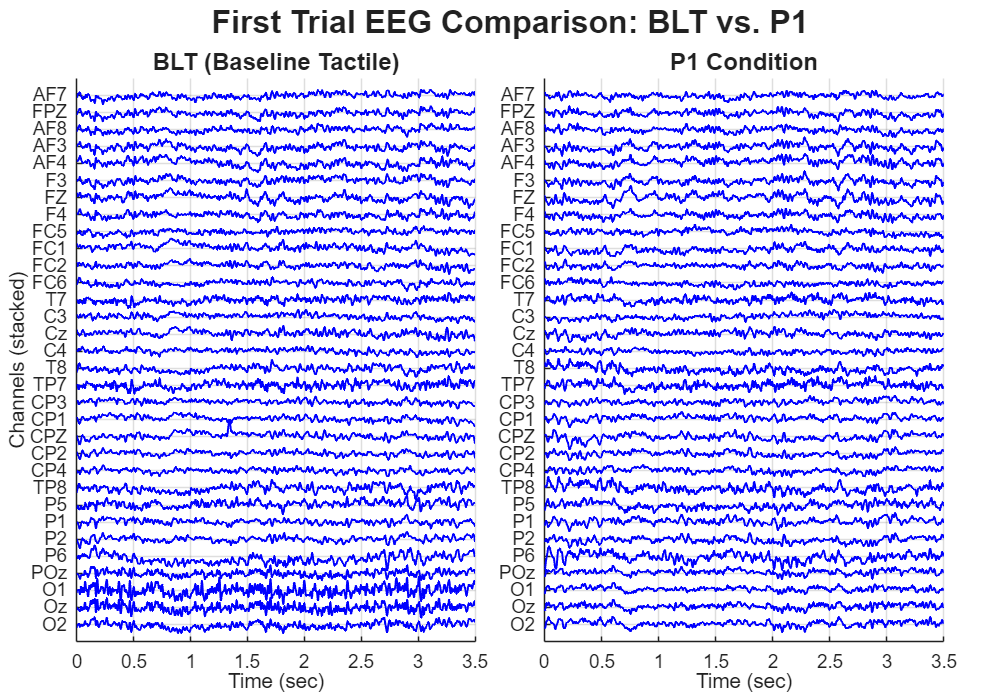

num_channels_plot = 32;
T_subject = 3.5; % duration of each trial
display_channels = 1:1:num_channels_plot;
display_channels_str = {EEG.chanlocs.labels};

% Made the figure slightly wider (1600) to comfortably fit two plots side-by-side
figure('Position',[50 50 2000 1400])
t = tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'First Trial EEG Comparison: BLT vs. P1', 'FontSize', 24, 'FontWeight', 'bold');

offset = 30; % vertical spacing between channels
tick_positions = (num_channels_plot - display_channels) * offset;

% =========================
% PLOT 1: BLT Condition
% =========================
nexttile;
hold on
for ch = 1:num_channels_plot
    plot(time_ms_eeg, squeeze(data_BLT(ch, :, 1)) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.5);
end
hold off

xlim([0 3.5]);
ylim([-offset, num_channels_plot*offset]);
xlabel('Time (sec)');
ylabel('Channels (stacked)');
yticks(flip(tick_positions));
yticklabels(flip(string(display_channels_str)));
set(gca,'FontSize',14);
title('BLT (Baseline Tactile)', 'FontSize', 18);
grid on;

% =========================
% PLOT 2: P1 Condition
% =========================
nexttile;
hold on
for ch = 1:num_channels_plot
    plot(time_ms_eeg, squeeze(data_P1(ch, :, 1)) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.5);
end
hold off

xlim([0 3.5]);
ylim([-offset, num_channels_plot*offset]);
xlabel('Time (sec)');
% Y-axis labels repeated for easy reading across the wide figure
yticks(flip(tick_positions));
yticklabels(flip(string(display_channels_str)));
set(gca,'FontSize',14);
title('P1 Condition', 'FontSize', 18);
grid on;